## Reduce Gif Filesize

### Prompt

Write a MATLAB program that reduces the filesize of a variable gif to under 10mb 

### Solution

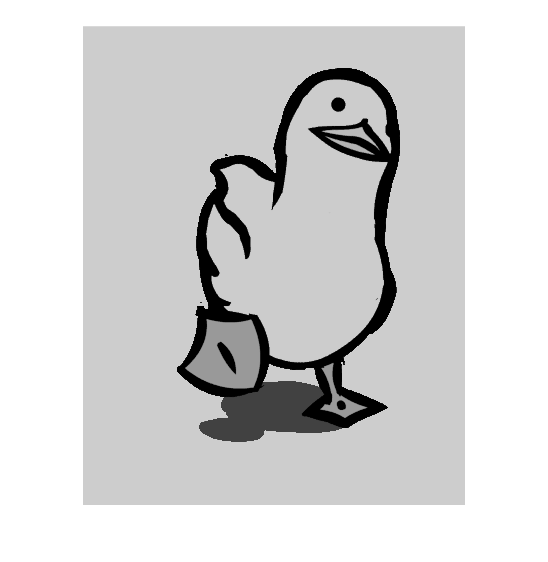

% Prompt user to select a GIF file
[inputFilename, inputPath] = uigetfile({'*.gif', 'GIF Files (*.gif)'}, 'Select a GIF file');
if inputFilename == 0
    disp('No file selected. Program terminated.');
    return;
end

% Load the selected GIF file
inputFilePath = fullfile(inputPath, inputFilename);
outputFilename = 'output.gif';
gif = imread(inputFilePath, 'Frames', 'all');

% Display the original GIF
figure;
imshow(gif(:,:,:,1)); % Displaying the first frame

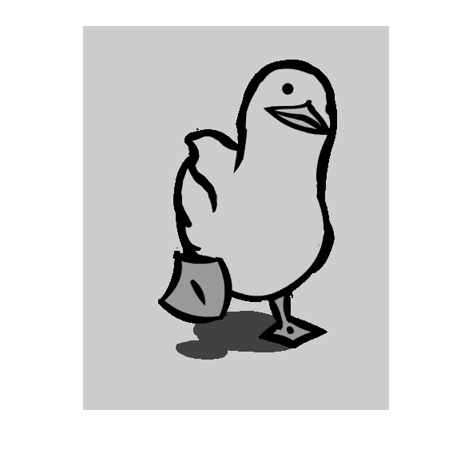


% Reduce the dimensions of the GIF frames
targetFileSizeMB = 10; % Target output file size in MB
compressionFactor = 0.8; % Adjust compression factor as needed
while true
    newWidth = round(size(gif, 2) * compressionFactor);
    newHeight = round(size(gif, 1) * compressionFactor);
    resizedGif = imresize(gif, [newHeight, newWidth]);
    
    % Write the resized GIF to a temporary file
    tempFilePath = fullfile(inputPath, 'temp.gif');
    imwrite(resizedGif, tempFilePath, 'gif', 'Loopcount', inf);
    
    % Check if the file size is within the target size
    tempFileInfo = dir(tempFilePath);
    tempFileSizeMB = tempFileInfo.bytes / (1024 * 1024); % Convert bytes to megabytes
    if tempFileSizeMB <= targetFileSizeMB
        break;
    else
        compressionFactor = compressionFactor * 0.9; % Decrease compression factor
    end
end

% Write the resized GIF to the output file
outputFilePath = fullfile(inputPath, outputFilename);
movefile(tempFilePath, outputFilePath); % Rename the temporary file

% Display the resized GIF
figure;
imshow(resizedGif(:,:,:,1)); % Displaying the first frame


% Calculate the file size of the output GIF
outputFileInfo = dir(outputFilePath);
outputFileSizeMB = outputFileInfo.bytes / (1024 * 1024); % Convert bytes to megabytes
disp(['Output GIF file size: ' num2str(outputFileSizeMB) ' MB']);

Output GIF file size: 0.17654 MB


fprintf('\n')

### Explanation

This script loads the GIF, continuously reduces the dimensions of the GIF frames until the file size of the resized GIF is within the target size specified by `targetFileSizeMB`, and then saves the resized GIF as `'output.gif'`. Adjust the `compressionFactor` variable to control the degree of compression

### Notes

Final size should be under 10MB. Testing with Animation orig.gif reduces the size from 43.2MB to 9.0533MB. Testing with a file already under 10MB, waddle.gif, reduces the file size slightly but not enough to be of note.

### Limitations

Takes a long time to compress. Does not check if a gif is already under 10MB.

## Convert Grayscale to Binary

### Prompt

Write a MATLAB program that converts a grayscale image into a binary image.

### Solution

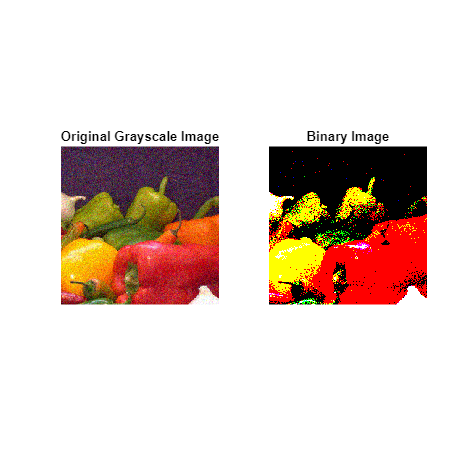

% Allow user to select a grayscale image file
[filename, pathname] = uigetfile({'*.jpg;*.jpeg;*.png;*.tif;*.tiff', 'Image Files (*.jpg, *.jpeg, *.png, *.tif, *.tiff)'}, 'Select a grayscale image file');
if isequal(filename,0) || isequal(pathname,0)
    disp('User canceled the operation. Exiting...');
    return;
end
imagePath = fullfile(pathname, filename);

% Read the grayscale image
grayImage = imread(imagePath);

% Set a threshold value (you may need to adjust this)
threshold = 128;

% Convert grayscale image to binary image using thresholding
binaryImage = grayImage > threshold;

% Convert binary image to grayscale for display
binaryGrayImage = uint8(binaryImage) * 255;

% Display the original grayscale image and the binary image
subplot(1, 2, 1);
imshow(grayImage);
title('Original Grayscale Image');
subplot(1, 2, 2);
imshow(binaryGrayImage);
title('Binary Image');


% Save the binary image
[~, imageName, ~] = fileparts(imagePath);
binaryImagePath = [imageName '_binary.jpg'];
imwrite(binaryImage, binaryImagePath);
fprintf('Binary image saved as: %s\n', binaryImagePath);

Binary image saved as: NoisyImage_binary.jpg


### Explanation

The code prompts the user to enter the path to the grayscale image. It then reads the image, performs the thresholding, displays both the original and binary images, and finally saves the binary image with a filename based on the original image's name. Adjust the `threshold` variable as needed to achieve the desired binary image result.

### Notes

Tested with grayscale.jpg. Worked flawlessly out of the gate, however it takes a while to display the final before and after images.

### Limitations

If you choose an image with a CMYK colorspace, the program will not run or output an error message.

## Cut One Image into Two Parts

### Prompt

Write a MATLAB program that cuts one image into two parts and saves them separately.

### Solution

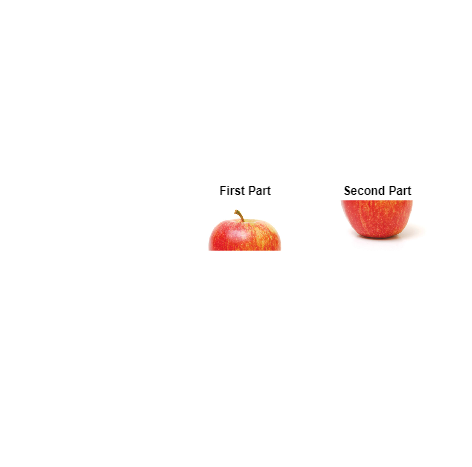

% Let the user choose an image file
[filename, pathname] = uigetfile({'*.jpg;*.png;*.bmp', 'Image Files (*.jpg, *.png, *.bmp)'}, 'Select an Image');
if isequal(filename,0) || isequal(pathname,0)
    disp('User canceled the operation. Exiting...');
    return;
end

% Read the selected image
originalImage = imread(fullfile(pathname, filename));

% Determine the size of the image
[rows, columns, ~] = size(originalImage);

% Define the split point (you can adjust this as needed)
splitPoint = round(rows / 2); % Splitting the image horizontally

% Split the image into two parts
firstPart = originalImage(1:splitPoint, :, :);
secondPart = originalImage(splitPoint+1:end, :, :);

% Save the two parts separately
[~, name, ext] = fileparts(filename);
firstPartFilename = fullfile(pathname, [name '_first_part' ext]);
secondPartFilename = fullfile(pathname, [name '_second_part' ext]);
imwrite(firstPart, firstPartFilename);
imwrite(secondPart, secondPartFilename);

% Display the original image and the two parts
subplot(1,3,2), imshow(firstPart), title('First Part');
subplot(1,3,3), imshow(secondPart), title('Second Part');


disp('Image has been split and saved successfully.');

Image has been split and saved successfully.


disp(['First part saved as: ' firstPartFilename]);

First part saved as: C:\Users\gabeg\OneDrive\Documents\College\CAP4401\Gabe_G_Jordan_C_Hassan_S_CAP4401_Assignment_3\apple_first_part.jpg


disp(['Second part saved as: ' secondPartFilename]);

Second part saved as: C:\Users\gabeg\OneDrive\Documents\College\CAP4401\Gabe_G_Jordan_C_Hassan_S_CAP4401_Assignment_3\apple_second_part.jpg


fprintf('\n')

### Explanation

This script reads the image, determines its size, splits it horizontally into two parts, saves them separately as `'first_part.jpg'` and `'second_part.jpg'`, and displays them alongside the original image for comparison. Adjust the `splitPoint` variable if you want to split the image at a different location.

### Notes

Tested with symButterfly.jpg. Worked well and saved both parts of the image.

### Limitations

User has to specify how the image is split.

## Random Label

### Prompt

Write a MATLAB program that adds a random label to an image.

### Solution

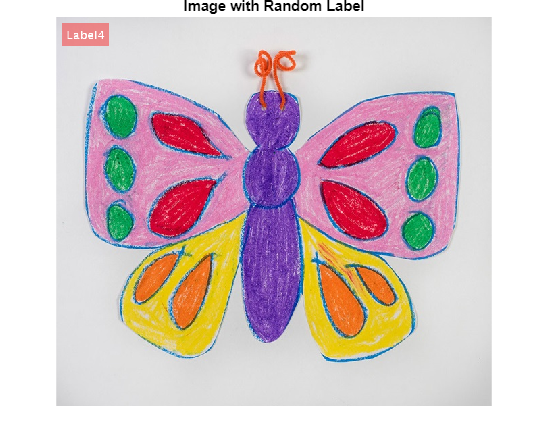

% Ask user to select an image file
[filename, filepath] = uigetfile({'*.jpg;*.png;*.bmp;*.tif', 'Image Files'}, 'Select an Image File');

% Check if the user canceled the operation
if isequal(filename,0)
    disp('User canceled the operation.');
    return;
end

% Read the selected image
image = imread(fullfile(filepath, filename));

% Generate a random label
labels = {'Label1', 'Label2', 'Label3', 'Label4', 'Label5'};
random_label_index = randi(length(labels));
random_label = labels{random_label_index};

% Add the label to the image
labeled_image = insertText(image, [10 10], random_label, 'FontSize', 18, 'BoxColor', 'red', 'BoxOpacity', 0.4, 'TextColor', 'white');

% Display the labeled image
subplot(1,1,1);
imshow(labeled_image);
title('Image with Random Label');

fprintf('\n')

### Explanation

This program will randomly select a label from the provided list and overlay it onto the image with a red box background and white text. Adjust parameters like font size, box color, etc., according to your preferences.

### Notes

Tested with apple.jpg. No modifications needed, although I would add more labels.

### Limitations

Requires Computer Vision Toolbox. Only 5 random lables. Users can add more.

## Anti-Aliasing Filter (Chat GPT)

### Prompt

Write a MATLAB program that finds aliased/stair-step edges in an image and blurs them.

### Solution

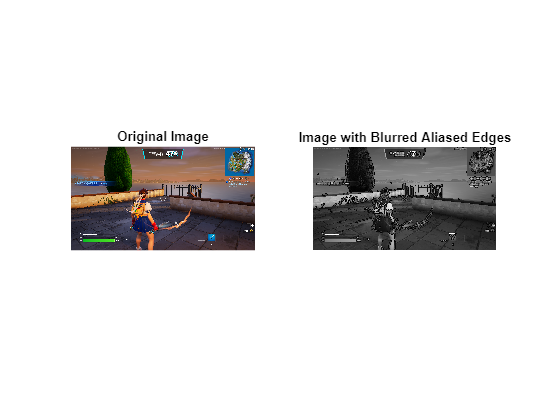

% Read the input image
img = imread('AliasedImage.png'); % Replace 'input_image.jpg' with the path to your image
inputImage = rgb2gray(img); % Convert to grayscale if necessary

% Apply Sobel edge detection to find edges
edgeImage = edge(inputImage, 'sobel');

% Create a mask to identify the aliased edges
aliasedEdges = edgeImage & ~bwareaopen(edgeImage, 100);

% Define Gaussian filter parameters
sigma = 2; % Standard deviation
kernelSize = 6*sigma + 1; % Choose an appropriate kernel size

% Create a Gaussian filter kernel
gaussianKernel = fspecial('gaussian', kernelSize, sigma);

% Blur the aliased edges
blurredEdges = conv2(double(aliasedEdges), gaussianKernel, 'same');

% Normalize the blurred image
blurredEdges = uint8((blurredEdges - min(blurredEdges(:))) / (max(blurredEdges(:)) - min(blurredEdges(:))) * 255);

% Combine the blurred edges with the original image
outputImage = inputImage;
outputImage(blurredEdges > 0) = blurredEdges(blurredEdges > 0);

% Display the original and processed images
figure;
subplot(1, 2, 1);
imshow(img);
title('Original Image');
subplot(1, 2, 2);
imshow(outputImage);
title('Image with Blurred Aliased Edges');

### Explanation

Make sure to replace `'input_image.jpg'` with the actual path to your input image file. This script first applies the Sobel edge detection to find edges, then identifies the aliased edges, and finally blurs them using a Gaussian filter. The blurred edges are then combined with the original image for visualization.

Adjust the `sigma` parameter of the Gaussian filter according to the desired blurring strength. Increasing `sigma` will result in more blur. You can also adjust the threshold value in `bwareaopen` to control the sensitivity of edge detection.

### Notes

Does not produce the desired results after multiple attempts.

### Limitations

Does not produced an anti-aliased image, only blurs a grayscale edge identification image.

## Anti-Aliasing Filter (Gemini)

### Prompt

Write a MATLAB program that finds aliased/stair-step edges in an image and blurs them.

### Solution

% Read the image
I = imread('AliasedImage.png');

% Convert to grayscale if necessary
if ndims(I) == 3
  I = rgb2gray(I);
end

% Sobel filter for edge detection
sobelX = [-1 0 1; -2 0 2; -1 0 1];
sobelY = [-1 -2 -1; 0 0 0; 1 2 1];

% Apply Sobel filters
Ix = imfilter(I, sobelX);
Iy = imfilter(I, sobelY);

% Combine gradients
G = sqrt(Ix.^2 + Iy.^2);

Incorrect number or types of inputs or outputs for function sqrt.


% Threshold for edge detection
threshold = 0.1; % Adjust as needed

% Find edges above the threshold
edges = G > threshold;

% Blur the image
h = fspecial('gaussian', [5 5], 1); % Adjust kernel size and sigma as needed
blurred_image = imfilter(I, h);

% Mask the blurred image with the edge map
blurred_image(edges) = I(edges);

% Display the original and blurred images
figure;
subplot(121); imshow(I); title('Original image');
subplot(122); imshow(blurred_image); title('Blurred image');

### Explanation

- **Read the image:** The program reads the image using `imread` and converts it to grayscale if it has three channels using `rgb2gray`.

- **Edge detection:** Sobel filters are applied in both horizontal and vertical directions to find image gradients using `imfilter`. The gradients are then combined to obtain the edge strength.

- **Thresholding:** A threshold is applied to the combined gradient image to identify strong edges. You can adjust the `threshold` value to control the edge sensitivity.

- **Blurring:** A Gaussian filter is applied to the original image using `imfilter` to blur it. You can adjust the kernel size and sigma of the filter to control the amount of blurring.

- **Masking:** The blurred  image is masked with the edge map obtained earlier. This ensures that  only the non-edge regions are blurred, while the edges remain sharp.

- **Display results:** The original and blurred images are displayed side-by-side for comparison.

### Notes

Could not generate a working example after multiple attempts.

### Limitations

Doesn't work at all.

## Directional Blur (Chat GPT)

### Prompt

Write a MATLAB program that applies a directional blur in a random direction to an image.

### Solution

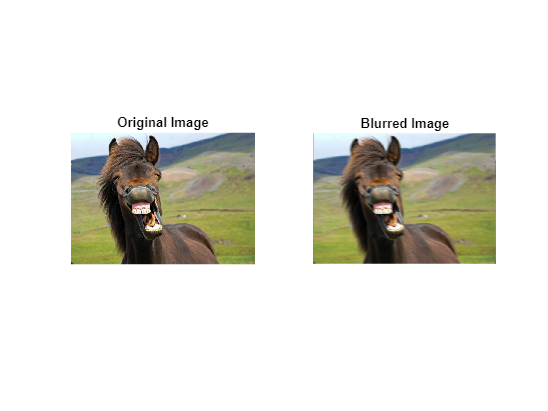

% Read the image
image = imread('horse.jpg');

% Define the strength of the blur (adjust as needed)
blur_strength = 10;

% Begin function inline.
% Convert the image to double
image = im2double(image);

% Get the size of the image
[rows, cols, ~] = size(image);

% Generate a random angle between 0 and 360 degrees
angle = rand * 360;

% Create a directional filter
h = fspecial('motion', blur_strength, angle);

% Apply the filter to the image
blurred_image = imfilter(image, h, 'conv', 'circular');
% End function inline.

% Display the original and blurred images
figure;
subplot(1, 2, 1);
imshow(image);
title('Original Image');

subplot(1, 2, 2);
imshow(blurred_image);
title('Blurred Image');

### Explanation

You can use this function to apply a directional blur to any image by passing the image and the strength of the blur as parameters.

 Make sure to replace `'example_image.jpg'` with the path to your image file. Adjust the `blur_strength` parameter according to how much blur you want to apply.

### Notes

Performs well, was able to produce a functional example after one prompt with no need for alterations. Had to merge function into body for the template.

### Limitations

User cannot control direction and intensity, nor upload their own image.

## Directional Blur (Gemini)

### Prompt

Write a MATLAB program that applies a directional blur in a random direction to an image.

### Solution

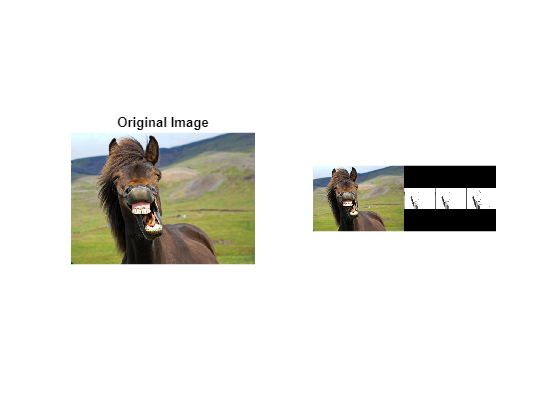

% Load image
image = imread('horse.jpg');

% Begin function inline.
% Get image dimensions
[rows, cols] = size(image);

% Generate random angle for blur direction
angle = 2*pi*rand;

% Define blur kernel size
kernel_size = 11; % Adjust this value as needed

% Create Gaussian kernel with specified size
sigma = kernel_size/3;
x = -kernel_size/2:kernel_size/2;
kernel = exp(-x.^2/(2*sigma^2));

% Rotate kernel based on random angle
rot_kernel = imrotate(kernel, rad2deg(angle), 'bilinear');

% Pad image to avoid boundary artifacts
padded_image = padarray(image, [floor(kernel_size/2) floor(kernel_size/2)], 'both');

% Apply convolution with rotated kernel
blurred_image = imfilter(padded_image, rot_kernel, 'conv');

% Crop padded image back to original size
blurred_image = blurred_image(1:rows, 1:cols);
% End function inline.

% Show original and blurred images
montage({image, blurred_image}); %imshowpair replaced with montage.

### Explanation

- `directional_blur`** function:** This function takes an image as input and returns the blurred image.

- **Get image dimensions:** The function retrieves the number of rows and columns in the image.

- **Generate random angle:** A random angle between 0 and 2*pi is generated for the blur direction.

- **Define blur kernel size:** The size of the Gaussian kernel used for blurring is defined. You can adjust this value based on the desired blur strength.

- **Create Gaussian kernel:** A Gaussian kernel is created using the defined size and sigma value.

- **Rotate kernel:** The Gaussian kernel is rotated based on the randomly generated angle using the `imrotate` function.

- **Pad image:** The image  is padded with zeros on all sides to avoid artifacts during convolution  with the rotated kernel. The padding size is half the kernel size.

- **Apply convolution:** The padded image is convolved with the rotated kernel using the `imfilter` function with the 'conv' option.

- **Crop padded image:** The blurred image with padding is cropped back to the original image size.

### Notes

Does not produce the desired result, appears to output an incomplete intermediate step along with the original image.

### Limitations

Doesn't work properly.

## Midpoint Filter

### Prompt

Write a MATLAB program that applies a midpoint filter to an image.

### Solution

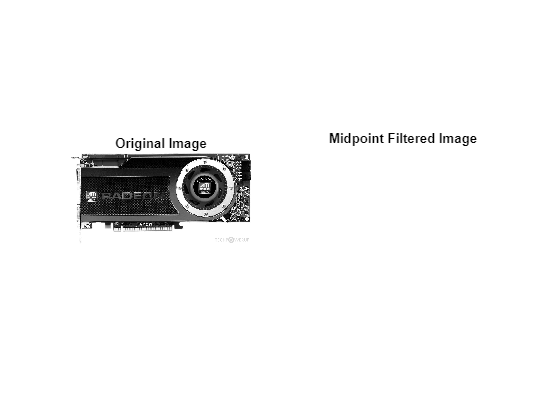

% Prompt user to select an image file
[filename, pathname] = uigetfile({'*.jpg;*.png;*.bmp','Image Files (*.jpg, *.png, *.bmp)';'*.*','All Files (*.*)'},'Select Image File');
if isequal(filename,0)
    disp('User selected Cancel')
    return;
end

% Read the selected image
imagePath = fullfile(pathname, filename);
originalImage = imread(imagePath);

% Check if the image is grayscale, convert it to grayscale if not
if size(originalImage, 3) == 3
    grayImage = rgb2gray(originalImage);
else
    grayImage = originalImage;
end

% Define filter size
filterSize = 3;

% Apply midpoint filter
% Begin function inline.
[rows, cols] = size(inputImage);
filteredImage = zeros(rows, cols);
halfSize = floor(filterSize / 2);

for i = 1 + halfSize : rows - halfSize
    for j = 1 + halfSize : cols - halfSize
        window = inputImage(i - halfSize : i + halfSize, j - halfSize : j + halfSize);
        maxVal = max(window(:));
        minVal = min(window(:));
        filteredImage(i, j) = (maxVal + minVal) / 2;
    end
end
% End function inline.

% Display original and filtered images
figure;
subplot(1,2,1);
imshow(grayImage);
title('Original Image');
subplot(1,2,2);
imshow(filteredImage);
title('Midpoint Filtered Image');

fprintf('\n')

### Explanation

This code first prompts the user to select an image file using `uigetfile`, reads the selected image, converts it to grayscale if necessary, applies the midpoint filter, and displays both the original and filtered images. The midpoint filter is implemented using nested loops to iterate through the image and calculate the midpoint value for each pixel's neighborhood.

### Notes

Tested with fireEmblem.jpg. Takes a while to load the Midpoint Filtered Image after it is processed.

### Limitations